clear all; clc; close all;
global N P measang
% Noise level
noise_level = 0.01;

N = 128;
target = phantom('Modified Shepp-Logan',N);
angle0  = -90;
measang = angle0 + [0:(N-1)]/N*180;
P  = length(radon(target,0));
NP = N*P; % size of y_obs
NN = N^2; % size of x / original image
observation = radon(target,measang);

% Add noise to the data
e = randn(size(observation));
y_obs  = observation + noise_level*max(max(observation))*e;
Data_var = (noise_level)^2; % Covariance matrix for data  \Sigma^{-1} = noise_level

## True solution

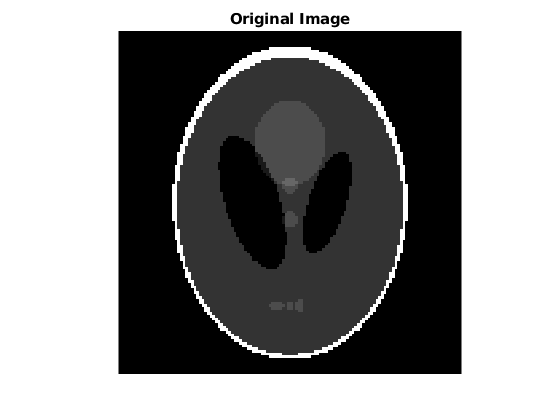

figure
Xtrue = reshape(target,[N,N]);
imagesc(Xtrue)
title('Original Image')
axis square; box off; axis off; colormap gray;
saveas(gcf,['X_ray_True'],'epsc')

load('DI_eigenvectors.mat')

R =            1         500        2000        5000       10000       12000


load('Eigvec_Active_normal.mat')

NN = [1, 2, 6, 9]

NN =      1     2     6     9


N = 128

N = 128

k = 1

ans =        16384           1


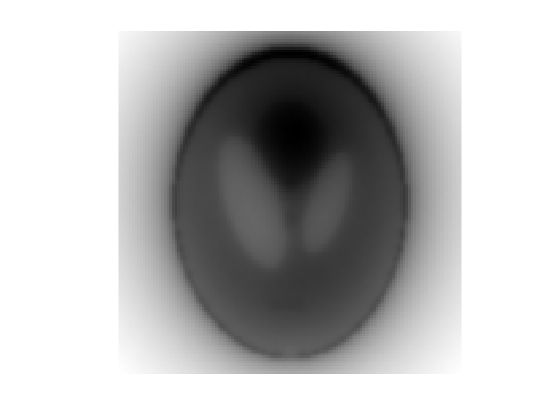

k = 2

ans =        16384           1


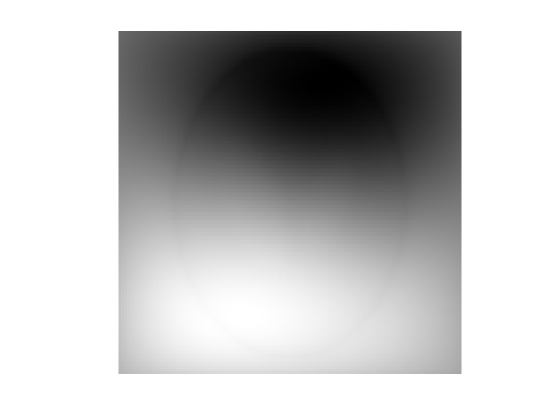

k = 6

ans =        16384           1


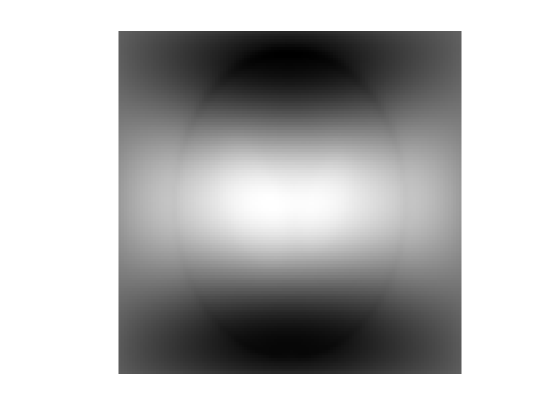

k = 9

ans =        16384           1


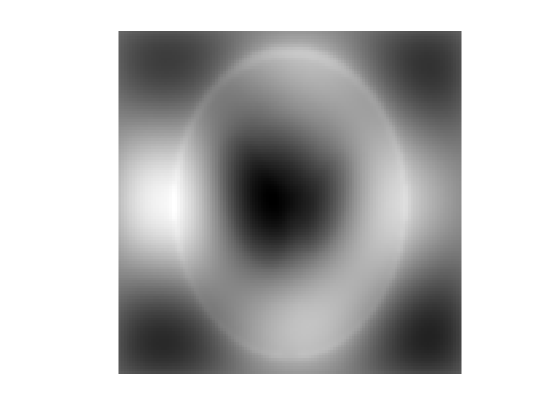



for i = 1:numel(NN)
    k = NN(i)
    size(W(:,k))
    
    figure
    Xtrue = reshape(W(:,k),[N,N]);
    imagesc(Xtrue)
    axis square; box off; axis off; colormap gray;
    saveas(gcf,['EigenW_' num2str(k)],'epsc')
end 

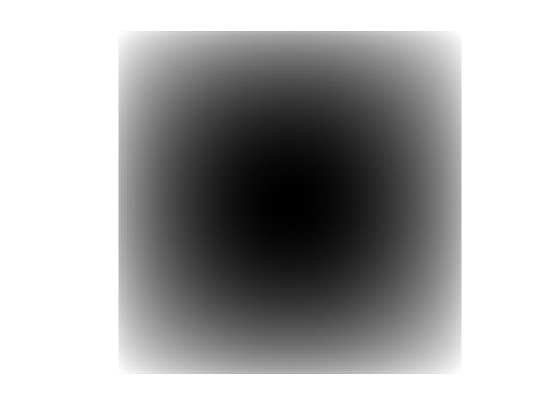

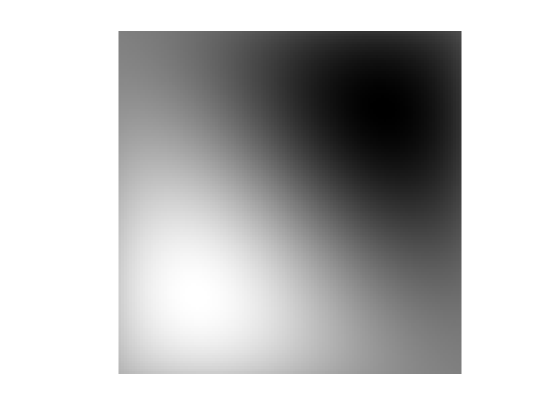

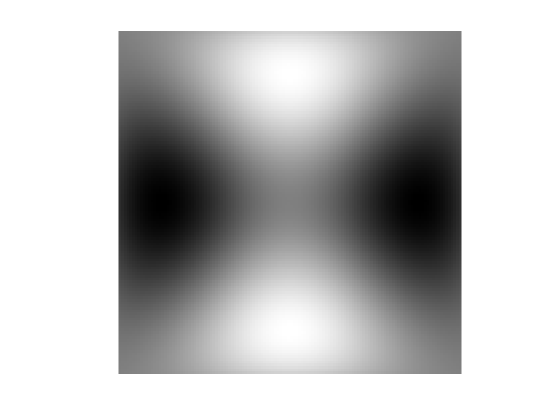

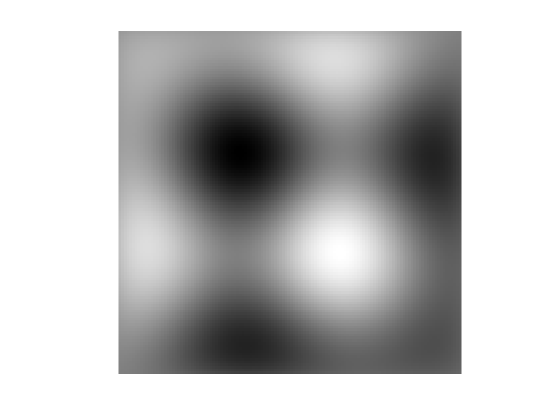


for i = 1:numel(NN)
    k = NN(i);
figure
% subplot(2,n,n + i)
Xtrue = reshape(V(:,k),[N,N]);
imagesc(Xtrue)
axis square; box off; axis off; colormap gray;
saveas(gcf,['EigenV_' num2str(k)],'epsc')
end

yuc(NN)

ans = 	1.0e+08 *

    1.5818
    0.6644
    0.4135
    0.3034


ycc(NN)

ans = 	1.0e+09 *

    2.6839
    0.0670
    0.0426
    0.0311
